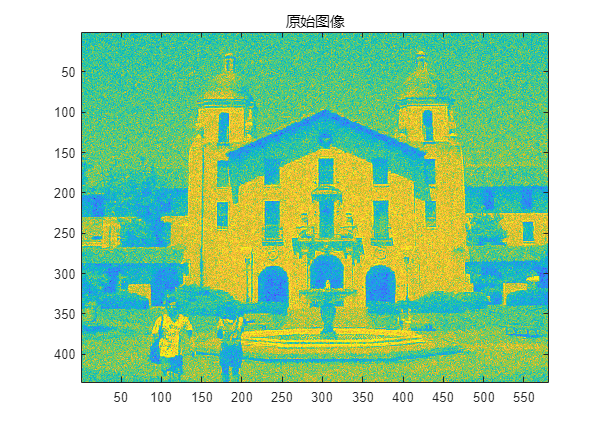

%%% 1  Convolutional operations
%% i. 显示图像

clc;
filename = 'C:\Users\HP\Desktop\上课\图像处理代码\lab6\For Students\lab6prob1data';
fileID = fopen(filename, 'rb'); 
imagedata = fread(fileID, [580, Inf], 'uint8'); 
% fclose(fileID);  % 关闭文件
image(imagedata');
axis('image')
title('原始图像');

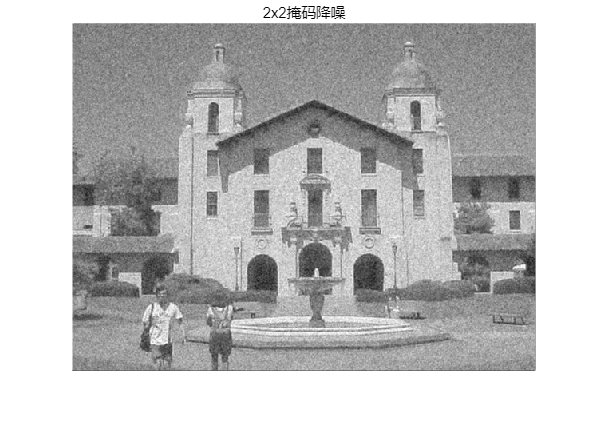

figure;
% 创建 2x2 和 3x3 全一掩码
mask2x2 = ones(2, 2);
mask3x3 = ones(3, 3);

% 使用 MATLAB 的 conv2 函数
filtered2x2 = conv2(imagedata', mask2x2, 'same');
filtered3x3 = conv2(imagedata', mask3x3, 'same');
a = customConv2(imagedata',mask3x3);

% 显示结果
figure, imshow(filtered2x2, []);
title('2x2掩码降噪');

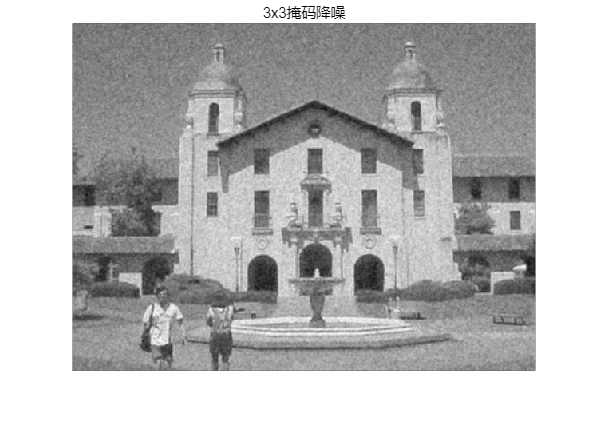

figure, imshow(filtered3x3, []);
title('3x3掩码降噪');

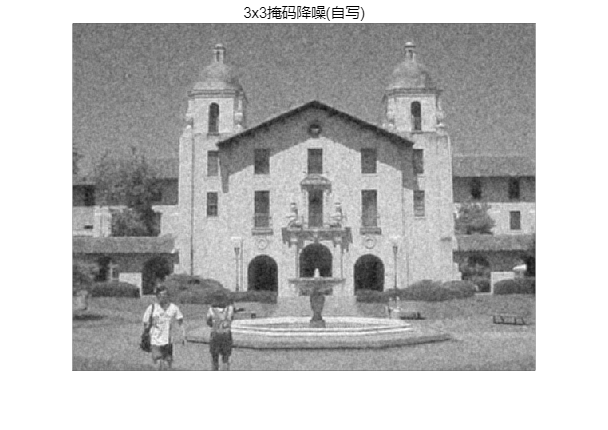

figure, imshow(a, []);
title('3x3掩码降噪(自写)');

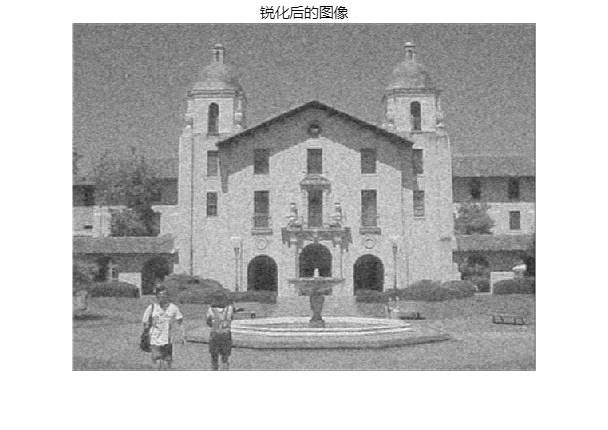

%% 2.拉普拉斯掩码
laplacianMask = [0 -1 0; 1 5 -1; 0 -1 0];

% 对 3x3 模糊图像进行锐化处理
sharpenedImage = conv2(filtered3x3, laplacianMask, 'same');
% 显示结果
figure, imshow(sharpenedImage, []);
title('锐化后的图像');

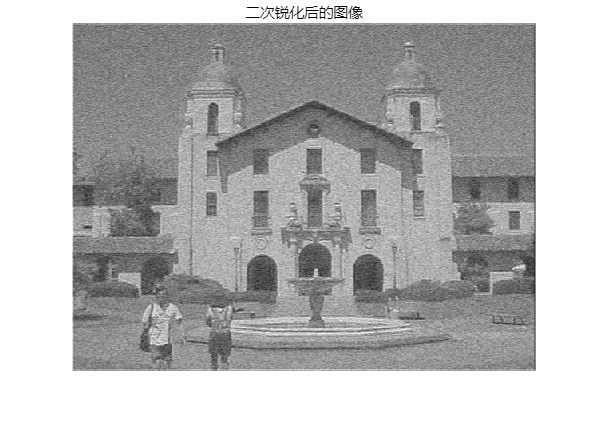

%% 3.再次进行锐化处理
sharpenedImage2 = conv2(sharpenedImage, laplacianMask, 'same');

% 显示结果
figure, imshow(sharpenedImage2, []);
title('二次锐化后的图像');

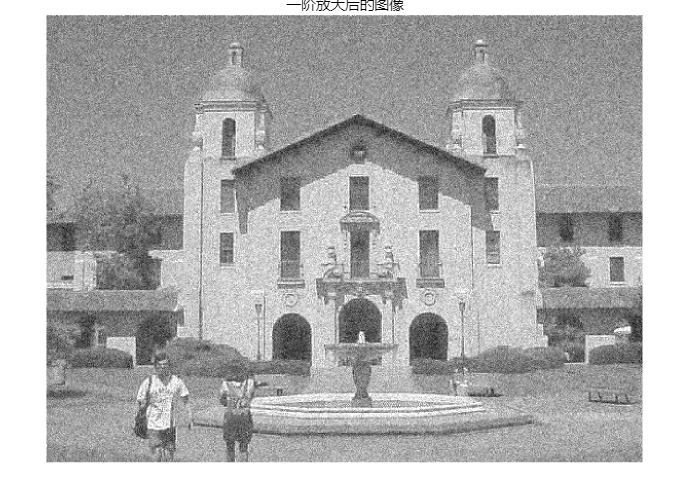

%% 4.一阶保持放大代码示例
zoomedImage = firstOrderZoom(imagedata', 2); % 放大两倍

% 显示结果
figure, imshow(zoomedImage, []);
title('一阶放大后的图像');

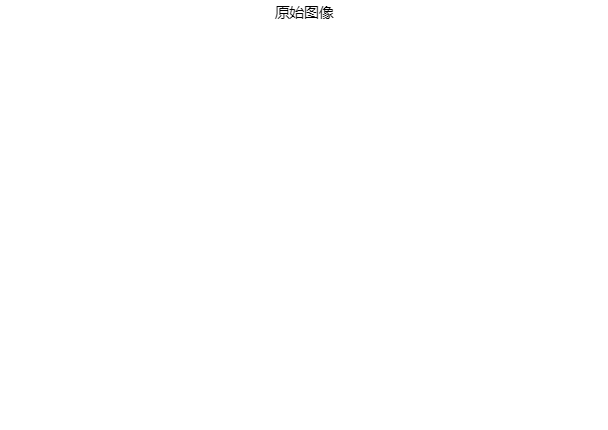

%% 5.二阶放大是怎么做的？？？？
% 读取图像
originalImage = im2gray(imagedata); % 转换为灰度图像

% 放大倍数
scaleFactor = 2;
% 创建零阶保持矩阵
zeroOrderMatrix = ones(scaleFactor) / (scaleFactor^2);

% 创建一阶保持矩阵
linearRamp = linspace(1 / scaleFactor, 1, scaleFactor);
firstOrderMatrix = linearRamp' * linearRamp;

% 计算二阶保持矩阵，通过将零阶保持矩阵与一阶保持矩阵卷积
secondOrderMatrix = conv2(zeroOrderMatrix, firstOrderMatrix, 'full');

% 使用二阶保持矩阵对图像进行放大
zoomedImage = conv2(double(originalImage), secondOrderMatrix, 'same');
zoomedImage = uint8(zoomedImage);

% 显示结果
figure, imshow(originalImage'), title('原始图像');

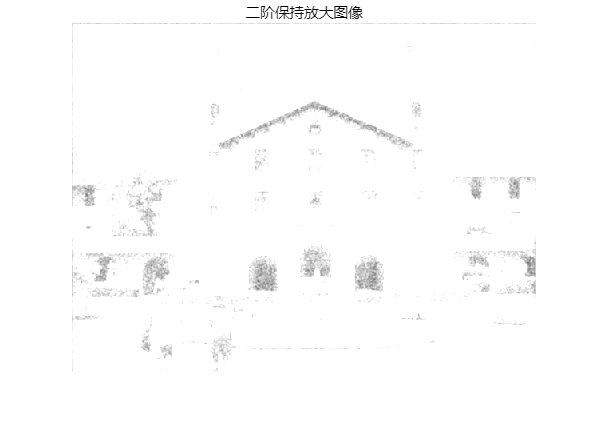

figure, imshow(zoomedImage'), title('二阶保持放大图像');

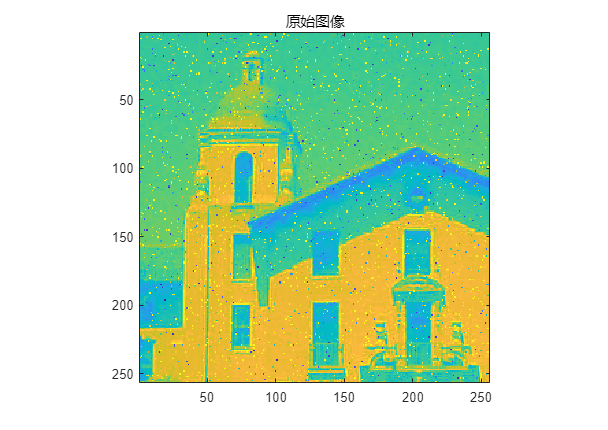

%%% 2 Shot noise

%% i 使用盒式滤波器

clc;
filename = 'C:\Users\HP\Desktop\上课\图像处理代码\lab6\For Students\lab6prob2data';
fileID = fopen(filename, 'rb'); 
imagedata2 = fread(fileID, [256, Inf], 'uint8'); 
%fclose(fileID);  % 关闭文件
image(imagedata2');
axis('image')
title('原始图像');

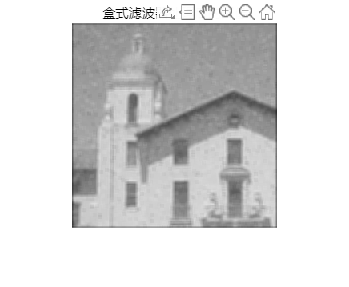

% 创建盒式滤波器
filterSize = 5;  
boxFilter = ones(filterSize) / (filterSize^2);

% 应用盒式滤波器
filteredImage = conv2(imagedata2', boxFilter, 'same');

% 显示结果
figure, imshow(uint8(filteredImage));
axis('image')
title('盒式滤波器处理后的图像');

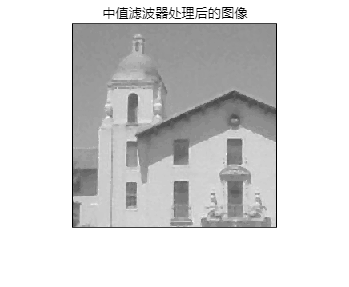

%% ii 使用中值滤波器

medianImage = customMedianFilter(imagedata2');

% 显示结果
figure, imshow(medianImage);
title('中值滤波器处理后的图像');

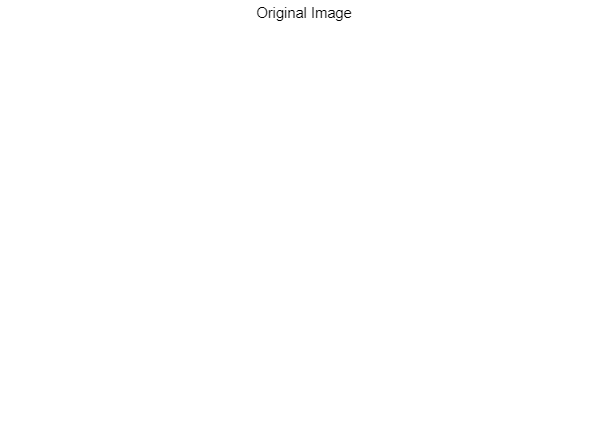

%%% 3 滤波
clc;
originalImage =imagedata'; 
imshow(imagedata'), title('Original Image');

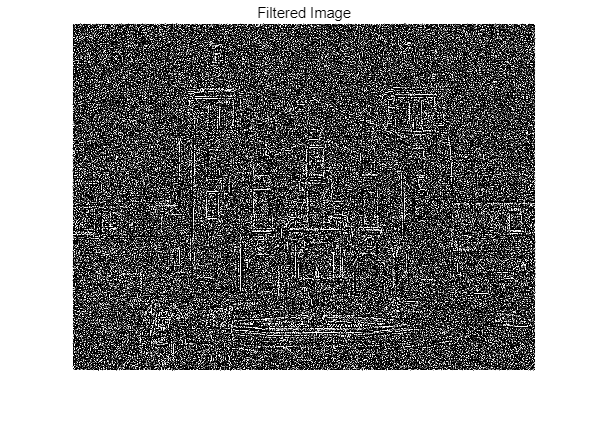


% 应用自定义滤波器
filteredImage = customEdgeDetectionFilter(originalImage);

% 显示处理后的图像
figure, imshow(filteredImage), title('Filtered Image');

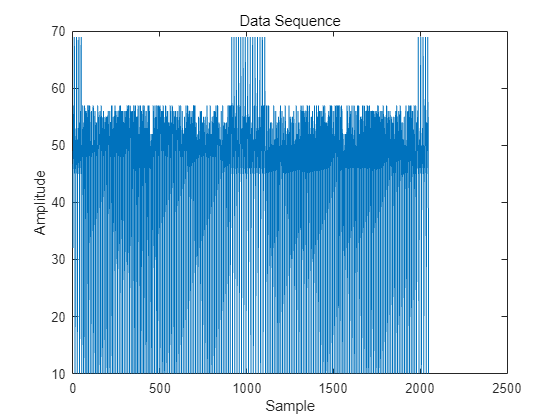

%%% 4.功率谱
%data = load -ASCII('C:\Users\HP\Desktop\上课\图像处理代码\lab6\For Students\lab6prob5data');
filename = 'C:\Users\HP\Desktop\上课\图像处理代码\lab6\For Students\lab6prob5data';
fileID = fopen(filename, 'rb'); 
data0 = fread(fileID); 
%i 绘制数据
figure, plot(data0);
title('Data Sequence');
xlabel('Sample');
ylabel('Amplitude');

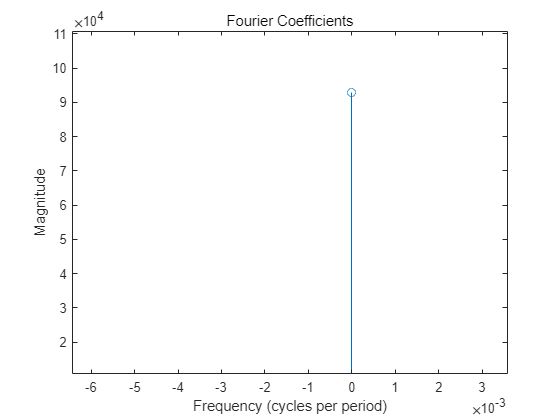

%% ii 计算离散傅里叶变换
N = length(data0); % 数据长度
fourierCoefficients = fft(data0);
frequencies = (0:N-1) * (1/N); % 频率范围

% 截取前20个傅里叶系数进行绘制
maxFrequency = 20;
frequencies = frequencies(1:maxFrequency);
fourierCoefficients = abs(fourierCoefficients(1:maxFrequency)); % 取绝对值

% 绘制傅里叶系数
figure, stem(frequencies, fourierCoefficients);
title('Fourier Coefficients');
xlabel('Frequency (cycles per period)');
ylabel('Magnitude');

function result = customConv2(image, kernel) %%%自写卷积方法
    [imgHeight, imgWidth] = size(image);
    [kernelHeight, kernelWidth] = size(kernel);

    % 计算填充的大小
    padHeight = floor(kernelHeight / 2);
    padWidth = floor(kernelWidth / 2);

    % 对图像进行零填充
    paddedImage = padarray(image, [padHeight, padWidth]);

    % 初始化结果矩阵
    result = zeros(imgHeight, imgWidth);

    % 执行卷积操作
    for x = 1 : imgHeight
        for y = 1 : imgWidth
            % 提取当前窗口
            window = paddedImage(x : x + kernelHeight - 1, y : y + kernelWidth - 1);

            % 应用卷积核
            result(x, y) = sum(sum(window .* kernel));
        end
    end
end


function zoomedImage = firstOrderZoom(image, scaleFactor) %%%一阶放大函数
    % 获取原始图像的尺寸
    [height, width] = size(image);

    % 计算放大后图像的尺寸
    newHeight = floor(height * scaleFactor);
    newWidth = floor(width * scaleFactor);

    % 初始化放大后的图像
    zoomedImage = zeros(newHeight, newWidth);

    % 对每个像素进行处理
    for i = 1:newHeight
        for j = 1:newWidth
            % 计算在原始图像中对应的坐标
            y = i / scaleFactor;
            x = j / scaleFactor;

            % 计算最近的整数像素坐标
            y_floor = floor(y);
            x_floor = floor(x);

            % 确保坐标在图像范围内
            y_floor = max(y_floor, 1);
            x_floor = max(x_floor, 1);
            y_floor = min(y_floor, height - 1);
            x_floor = min(x_floor, width - 1);

            % 计算比例因子
            dy = y - y_floor;
            dx = x - x_floor;

            % 线性插值
            top = (1 - dx) * image(y_floor, x_floor) + dx * image(y_floor, x_floor + 1);
            bottom = (1 - dx) * image(y_floor + 1, x_floor) + dx * image(y_floor + 1, x_floor + 1);

            zoomedImage(i, j) = (1 - dy) * top + dy * bottom;
        end
    end

    % 转换为合适的数据类型
    zoomedImage = uint8(zoomedImage);
end

function zeroOrderMatrix = zeroOrderHold(scaleFactor) %%%零阶保持矩阵
    % 零阶保持放大矩阵，简单复制像素
    zeroOrderMatrix = ones(scaleFactor) / (scaleFactor^2);
end

function firstOrderMatrix = firstOrderHold(scaleFactor) %%% 一阶保持矩阵
    % 一阶保持矩阵，线性插值
    linearRamp = linspace(1 / scaleFactor, 1, scaleFactor);
    firstOrderMatrix = linearRamp' * linearRamp;
end

function zoomedImage = secondOrderZoom(image, scaleFactor) %%% 二阶放大矩阵
    % 生成零阶和一阶保持矩阵
    zeroOrderMat = zeroOrderHold(scaleFactor);
    firstOrderMat = firstOrderHold(scaleFactor);

    % 二阶保持矩阵是这两个矩阵的卷积
    secondOrderMat = conv2(firstOrderMat, zeroOrderMat, 'full');

    % 应用二阶保持矩阵进行放大
    zoomedImage = conv2(double(image), secondOrderMat, 'same');
    zoomedImage = uint8(zoomedImage);
end

function medianFilteredImage = customMedianFilter(image) %% 中值滤波
    [height, width] = size(image);
    medianFilteredImage = zeros(height, width);

    for i = 2:height-1
        for j = 2:width-1
            % 提取3x3邻域
            window = double(image(i-1:i+1, j-1:j+1));
            
            % 应用中值滤波
            medianFilteredImage(i, j) = median(window(:));
        end
    end

    medianFilteredImage = uint8(medianFilteredImage);
end

% 自定义边缘检测滤波器
function filteredImage = customEdgeDetectionFilter(image)
    % 定义一个简单的边缘检测核
    kernel = [-1 -1 -1; -1 8 -1; -1 -1 -1];

    % 应用卷积
    filteredImage = conv2(double(image), kernel, 'same');
    filteredImage = uint8(filteredImage);
end

